# **CONTINUM > Example 01**

**A first example: An ODE system**

We want to find a Hopf bifurcation point for the following system of equations:

## 
$$\begin{array}{l}
\frac{\textrm{du}}{\textrm{dt}}=1-\mathrm{u}\left(1+{\textrm{Da}\cdot \mathrm{e}}^{\mathrm{v}} \right)\\
\frac{\textrm{dv}}{\textrm{dt}}=\mathrm{B}\cdot \;\textrm{Da}\cdot \;\mathrm{u}\cdot {\textrm{e}}^{\mathrm{v}} -\mathrm{v}\left(1+\textrm{beta}\right)
\end{array}$$


First, we need to create a file in which those equations are implemented:

This file was saved as **cstr_simple.m**

Now, we are able to use the Continum package.

## **1) Create the Variables**

clc
clear

% Syntax: var = Variable(tag, var0);
%         tag:  is the display name (all tags must be unique).
%         var0: is used as initial guess (steady state solution)
%               or initial condition (dynamic solution).
u = Variable('u', 1);
v = Variable('v', 1);

## 2) Create the Parameters

% Syntax: par = Parameter(tag, par0, lb, ub, fixed); 
%         tag:   is the display name (all tags must be unique).
%         par0:  is used as initial guess.
%         lb:    is the parameter lower bound.
%         ub:    is the parameter upper bound.
%         fixed: is a boolean: false (default), when the parameter
%                is used in search; true, when it is fixed.
Da = Parameter('Da', 1, 0, 10);
B = Parameter('B', 14, 0, 50, true);
beta = Parameter('\beta', 3, 0, 10, true);

## 3) Create the problem

P = Continum(@cstr_simple, [u, v], [Da, B, beta]); 
% Variables and parameters's positions must be consistent
% with the definitions in 'cstr_simple.m' file

% Show initial model analysis
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple.m
    Variables ....................................... u = 1, v = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 0
    Explicit Algebraic Eqs .......................... 0
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2


================= End of Report =================



## 4) Simulate

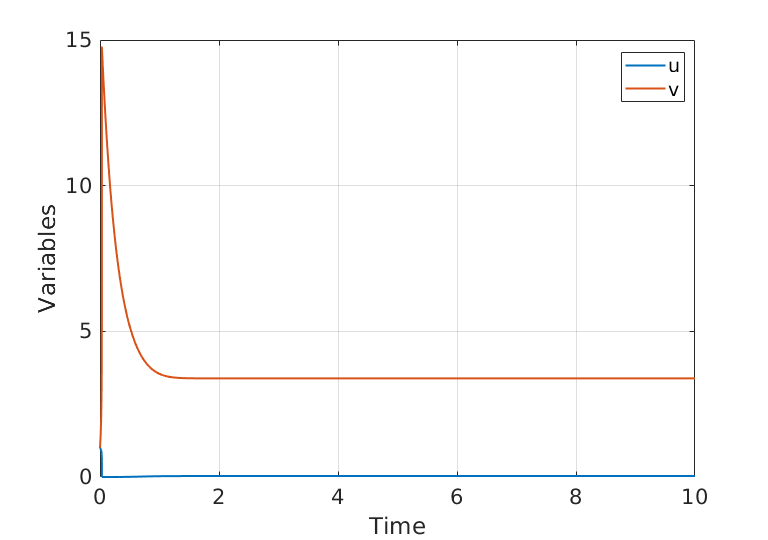

% Setup the integrator:
P.dynopt.abstol = 1e-10;
P.dynopt.reltol = 1e-08;
P.dynopt.solver = 'ode15s';

% Simulate
P.Simulate([0,10]);

% Plot time series
P.PlotTimeSeries([u,v]);

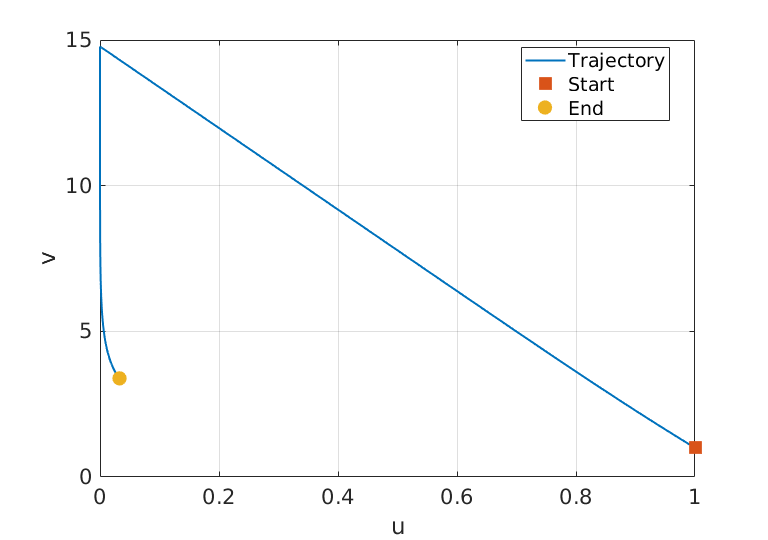

% Plot phase plane
P.PlotPhasePlane(u,v)

## 5) Hopf Search

% Setup optimizer:
P.optopt.algorithm = 'simplex'; % {'simplex','hybrid','swarm','levenberg-marquardt'}
P.optopt.display = 'iter'; % {'none','iter'}
P.optopt.objectiveform = 'absolute'; % {'absolute', 'quadratic'}
P.optopt.tolfun = 1e-10;
P.optopt.tolx = 1e-10;
P.optopt.display = 'none';

% HopfSearch
P.HopfSearch;
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple.m
    Variables ....................................... u = 1, v = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 0
    Explicit Algebraic Eqs .......................... 0
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 1.202411e-01, v = 3.079156e+00
    par-values ...................................... Da = 3.365505e-01
    Eigenvalues ..................................... (1.9459e-08 +4.5771e+00i, 1.9459e-08 -4.5771e+00i)

    CPU Time ........................................ 1.590953e+00 s
    Ob

% Keep the bifurcation point
P.KeepBP;
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple.m
    Variables ....................................... u = 1, v = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 0
    Explicit Algebraic Eqs .......................... 0
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 1.202411e-01, v = 3.079156e+00
    par-values ...................................... Da = 3.365505e-01
    Eigenvalues ..................................... (1.9459e-08 +4.5771e+00i, 1.9459e-08 -4.5771e+00i)

    CPU Time ........................................ 1.590953e+00 s
    Ob

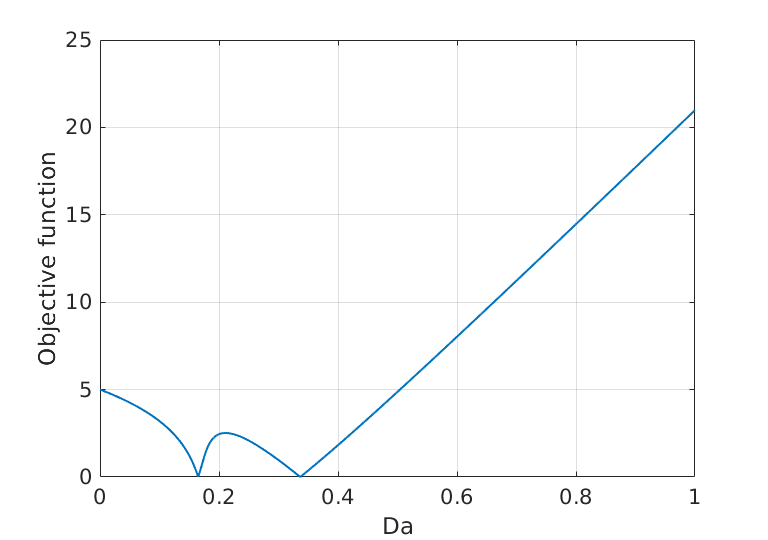

% Plot objective function around hopf for graphical aid
P.PlotObjectiveFunction(Da, 1000, [0 1])

% Change bounds to get another hopf
P.SetUpper(Da, 0.2)


	 Class: Parameter
	 Tag:   Da
	 Value: 2.0000e-01
	 Lower: 0.0000e+00
	 Upper: 2.0000e-01
	 Fixed: no


P.SetValue(Da, 0.1)


	 Class: Parameter
	 Tag:   Da
	 Value: 1.0000e-01
	 Lower: 0.0000e+00
	 Upper: 2.0000e-01
	 Fixed: no


% Make another search
P.HopfSearch;

% New results
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple.m
    Variables ....................................... u = 1.202411e-01, v = 3.079156e+00
    Search Parameters ............................... Da = 1.000000e-01
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 0
    Explicit Algebraic Eqs .......................... 0
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 5.940446e-01, v = 1.420844e+00
    par-values ...................................... Da = 1.650420e-01
    Eigenvalues ..................................... (2.8234e-08 +1.0248e+00i, 2.8234e-08 -1.0248e+00i)

    CPU Time .............................

% Keep new hopf
P.KeepBP;
P.ShowReport



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple.m
    Variables ....................................... u = 1.202411e-01, v = 3.079156e+00
    Search Parameters ............................... Da = 1.000000e-01
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 0
    Explicit Algebraic Eqs .......................... 0
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 5.940446e-01, v = 1.420844e+00
    par-values ...................................... Da = 1.650420e-01
    Eigenvalues ..................................... (2.8234e-08 +1.0248e+00i, 2.8234e-08 -1.0248e+00i)

    CPU Time .............................

## 6) Continuation

% Steady state continuation
P.SSContinuation(Da, 1000, [0.0,0.7])


Runing steady-state continuation...

Iter: 1000	 norm: 1.790181e-15

Finished!

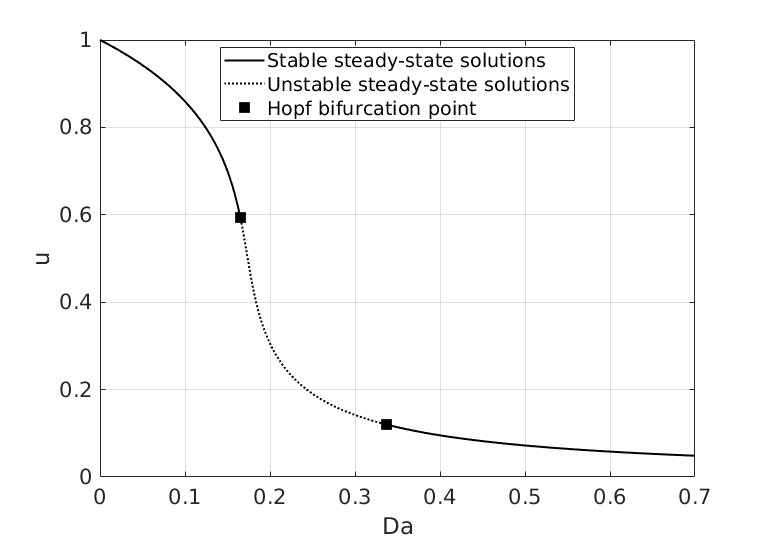

% Plot the branch diagram
P.PlotBranchDiagram(Da, u)

% Periodic continuation
P.ShiftToBP(2)
P.conopt.ds = 1e-2;
P.conopt.kmax = 140;
P.conopt.fixedDs = false;
P.conopt.algorithm = 'trust-region-reflective';
P.conopt.display = 'none';

P.PeriodicContinuation(Da);

Searching for initial orbit...


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0        162          0.0001                       0.00145
     1        324      1.0128e-06      0.0133665         0.0941      
     2        486     7.25669e-12      0.0016013        0.00183      
     3        648     7.25669e-12      0.0139515        0.00183      
     4        810     7.25669e-12     0.00348788        0.00183      
     5        972     7.25669e-12    0.000871971        0.00183      
     6       1134     7.04112e-12    0.000217993        0.00149      
     7       1296     6.92919e-12    0.000217993        0.00107      
     8       1458     6.86375e-12    0.000217993       0.000891      
     9       1620     6.84268e-12    0.000217993       0.000742      
    10       1782     6.80251e-12    5.44982e-05       0.000714      



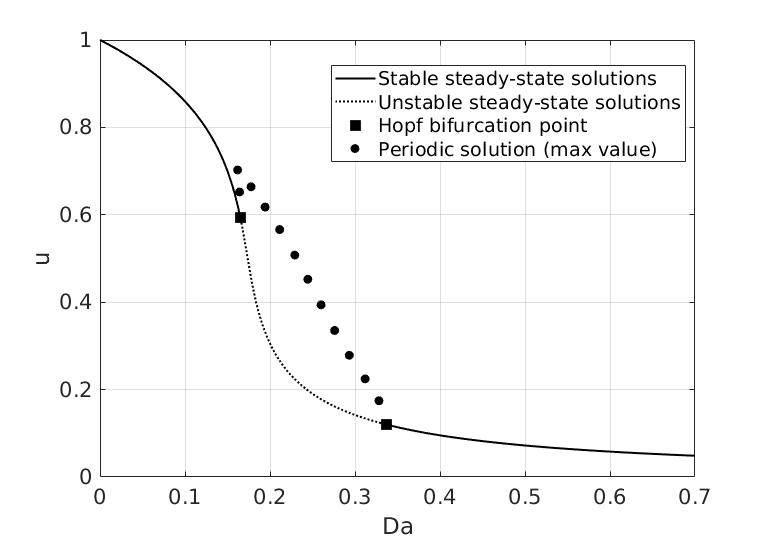

P.PlotBranchDiagram(Da, u)

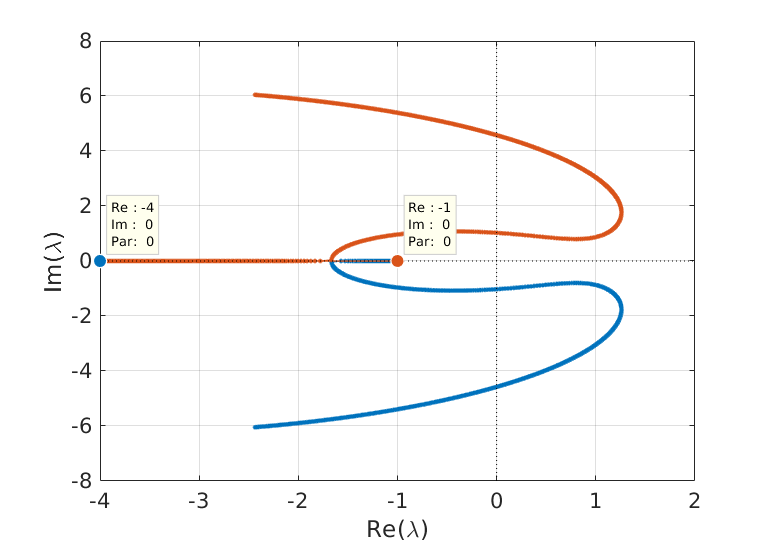

P.PlotEigenMap(Da, 1000, [0 0.5])

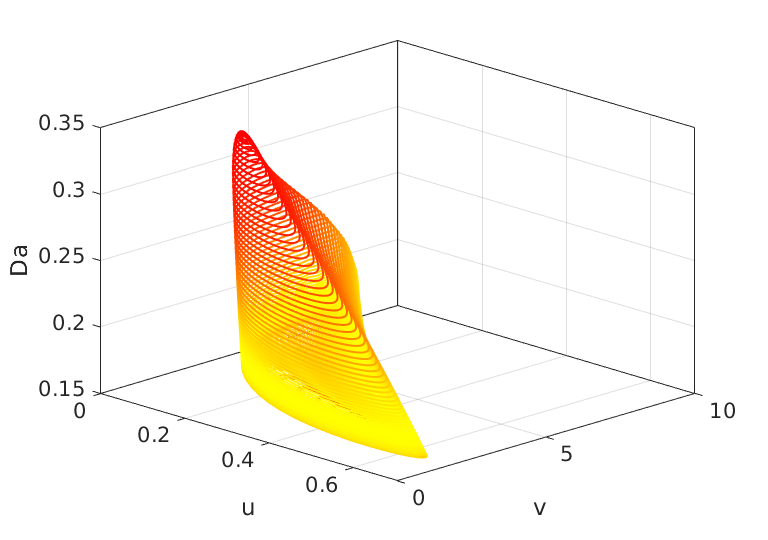

P.PlotOrbitSurface(Da, u, v, [], @autumn)